# Assignment 2: Task 2

## Load experiment data

if (~exist("session2","var"))
    load("group-01.02.mat");
end

f = session2.task2.frequency;
R0 = session2.task2.antennas_distance;
H = session2.task2.reflection_height(1);
epsilon1 = 8.854e-12;

## Free space

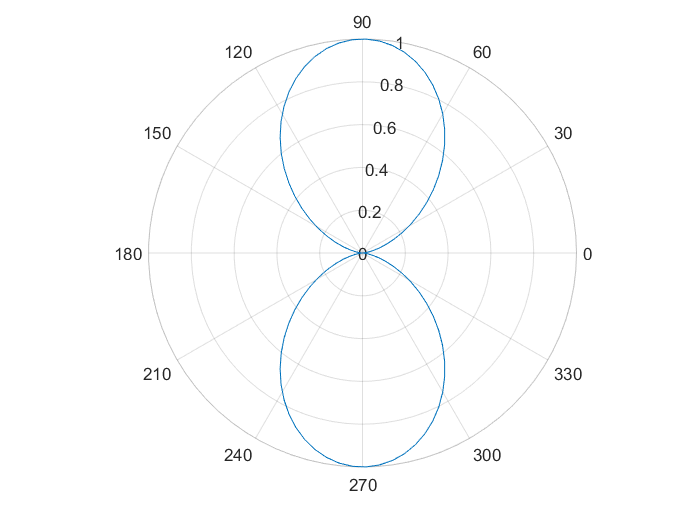

epsilon2 = epsilon1;

% Vertical
tau = 0;
phi = 0.5*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

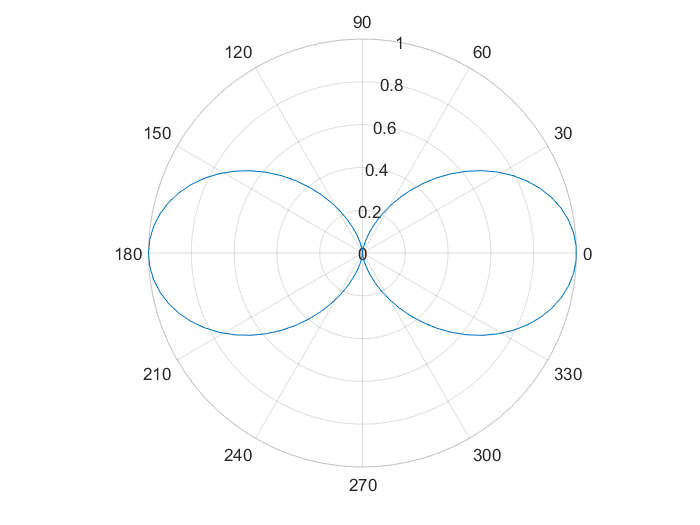

% Horizontal
tau = 0;
phi = 0.0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

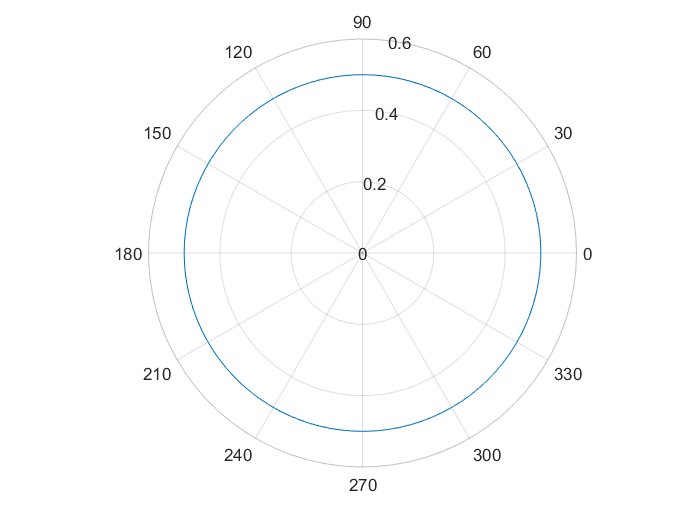

% Circular
tau = 0.25*pi;
phi = 0.0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

## Metallic plate

epsilon2 = -1e10j * epsilon1;

% Vertical
tau = 0;
phi = 0.5*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

% Horizontal
tau = 0;
phi = 0.0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

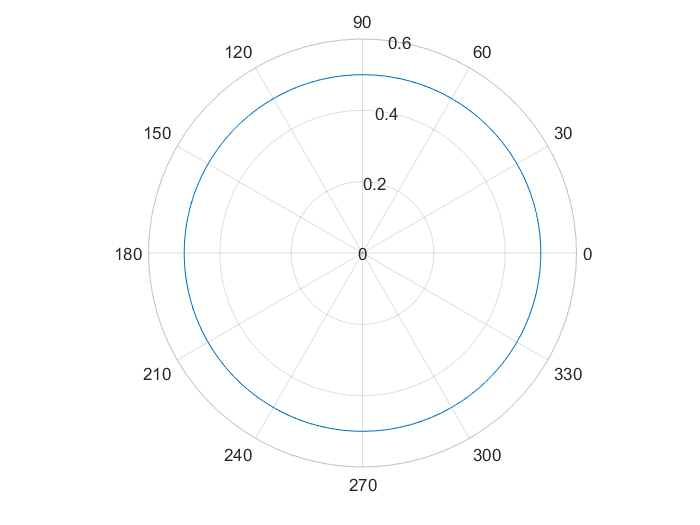

% Circular
tau = 0.25*pi;
phi = 0.0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

## Dielectric Plate

epsilon2 = session2.task2.dielectric_prermittivity; epsilon2 = epsilon2 * 8.8541878128e-12;

% Vertical
tau = 0;
phi = 0.5*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

% Horizontal
tau = 0;
phi = 0.0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

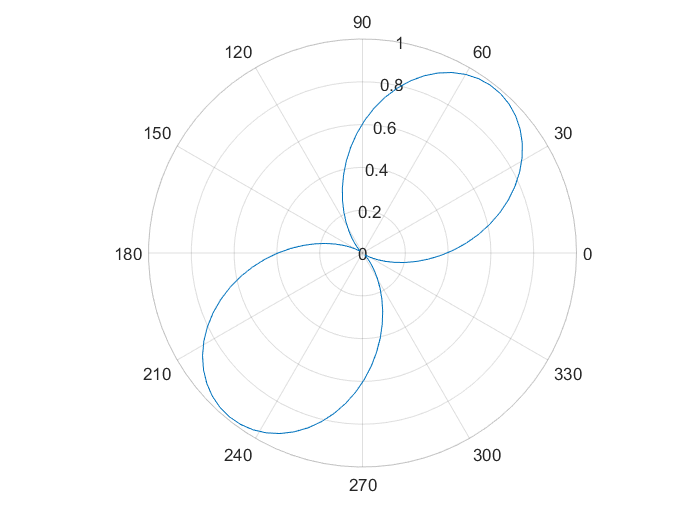

% Circular
tau = 0.25*pi;
phi = 0.0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)

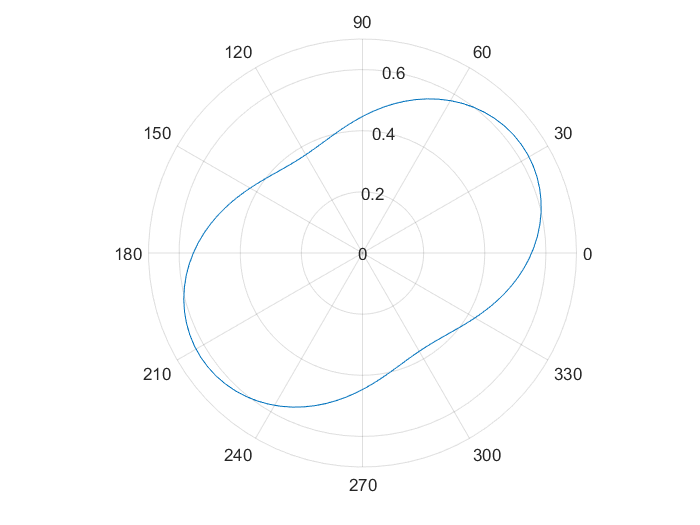

% Random
phi = 0.2*pi;
tau = 0*pi;
angular_pattern(f,R0,H,tau,phi,epsilon1,epsilon2)